# Mean crustal properties

clear

The discussion of layered media can be used to estimate the mean premeability of the crustal aquifer from the decay of permeability with depth. Several model for vertical variation have been suggested. Here we use one of the simpler ones, suggested by Clifford and Parker (2001).

## Porosity

Clifford and Parker (2001) argue that the Martian porosity decays similarly to the estimated porosity decay on the Moon, scaled for increased gravity on Mars. The original model for the porosity of the Moon is from Binder and Lange (1980) and given by $\phi_{Moon} = 0.2\, \mathrm{e}^{-d/6.5}$ (this is in caption of Fig 1 of their paper!), where $d$ is the depth in km. 

phi = @(d,phi0,d0) phi0*exp(-d/d0);

This model of porosity decay has essentially been confirmed by the recent GRAIL mission that found that the Moon has a ﻿megaregolith with surface porosity between 0.1 and 0.2, which is eliminated at 10-20km depth (Han et al. 2014).

Given the Moon/Mars gravity ratio of 

gMars = 3.711;  % [m/s^2] Mars gravity
gMoon = 1.62;   % [m/s^2] Moon gravity
gratio = gMoon/gMars

gratio = 0.4365

the porosity decay constant is reduced to

d0Moon = 6.5;           % [km] porosity decay depth on Moon
d0Mars = 6.5*gratio     % [km] porosity decay depth on Mars

d0Mars = 2.8375

and a tey assume a range on reference porosities between

phi0_min = 0.3;
phi0_max = 0.5;

Hence we have the porosity decay with depth shown in Figure M1

d = linspace(0,10,1e2);
clf
subplot 121
plot(phi(d,phi0_min,d0Mars),d), hold on
plot(phi(d,phi0_max,d0Mars),d)
set(gca,'ydir','reverse')
xlabel '\phi [-]', ylabel 'd [km]'

## Permeability

Since there are no direct permeability measurement of the fractures crust of either the Moon or Mars, Clifford and Parker (2001) assume a permeability decay similar to that observed on Earth. Manning and Ingebritsen (1999) determined an average crustal permeability from a wide range of data shown in the graph below.

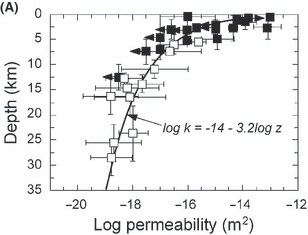

Again they scaled the depth, $d$, with the Mars/Earth gravity ratio to obtain the relation


$$\log_{10}(k) = -12.65 - 3.2\,\log_{10}(d)$$


which can be written as a power-law


$$k(z) = k_0\, d^{-\alpha}$$
 

with $k_0 = 10^{-12.65} = 2.24\cdot10^{-13}$, $\alpha =3.2$, and $d$ in km. 

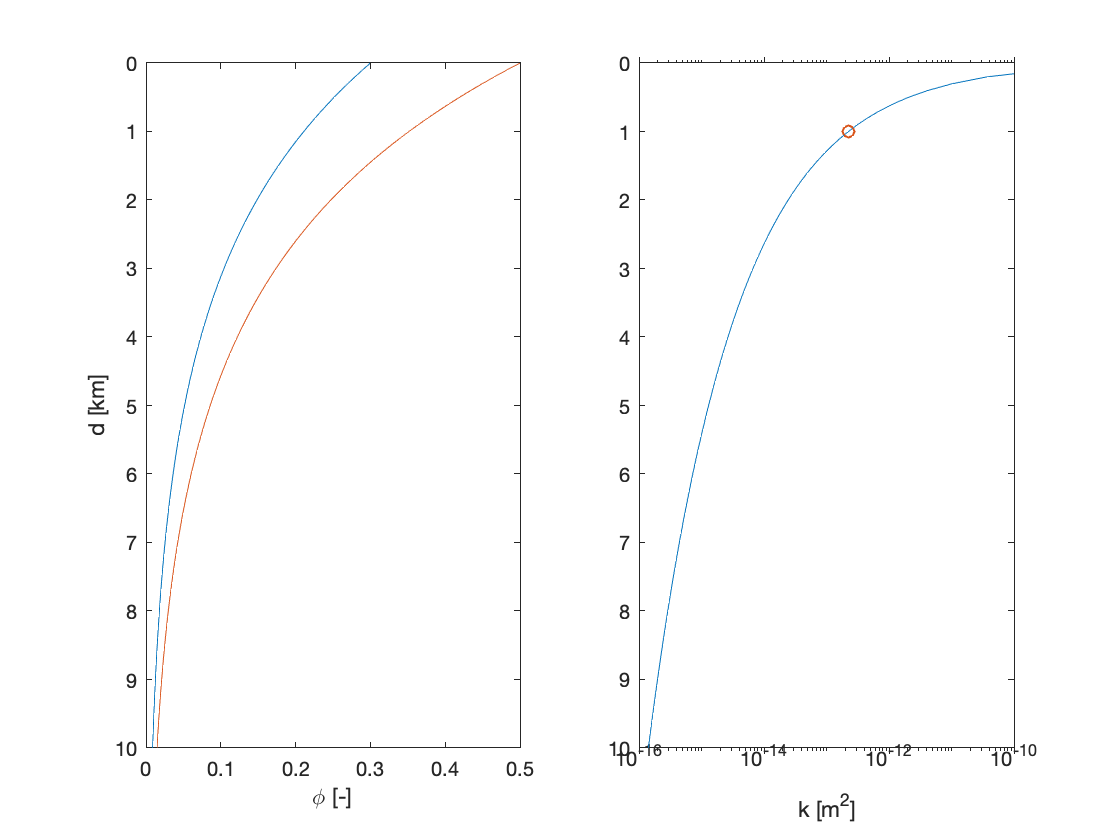

k0 = 10^(-12.65); % [m^2] ref. permeability at 1km depth
alpha = 3.2;
k = @(d) k0*d.^(-alpha);

subplot 122
semilogx(k(d),d), hold on
semilogx(k0,1,'o')
set(gca,'ydir','reverse')
xlabel 'k [m^2]', xlim([1e-16 1e-10])

Note that this permeability model predicts unreasonably high permeabilities at depth shallower than 1 km.

## Mean permeability

For our one-dimensional aquifer model we need an average value of permeability. Since flow is horizontal and hence 'along the layers' we can compute the effective permeability using the arithmetic average. For a continous function, $k(d)$, the arithmetic average between two depth, $d_\mathrm{min}$ and $d_\max$ is defined as


$$\bar{k} = \frac{1}{\Delta d}\int_{d_\min}^{d_\max}k(z)\mathrm{d}z = \frac{k_0}{(\alpha+1)\Delta d}\left(d_\min^{-(\alpha+1)}-d_\max^{-(\alpha+1)}\right)$$
 

kmean = @(dmin,dmax)k0/(alpha+1)/(dmax-dmin)*(dmin^(-(alpha+1))-dmax^(-(alpha+1)))

kmean = function_handle with value:
    @(dmin,dmax)k0/(alpha+1)/(dmax-dmin)*(dmin^(-(alpha+1))-dmax^(-(alpha+1)))


 This mean is very sensitive to $d_\min$ as shown below for an aquifer with $d_\max = 10
$km and variable $d_\min$ between 0.5 and 1.5 km. The mean permeability, $\bar{k}$, drops two orders of magnitude from $10^{-13}$ to $10^{-15}$ $\mathrm{m}^2$!

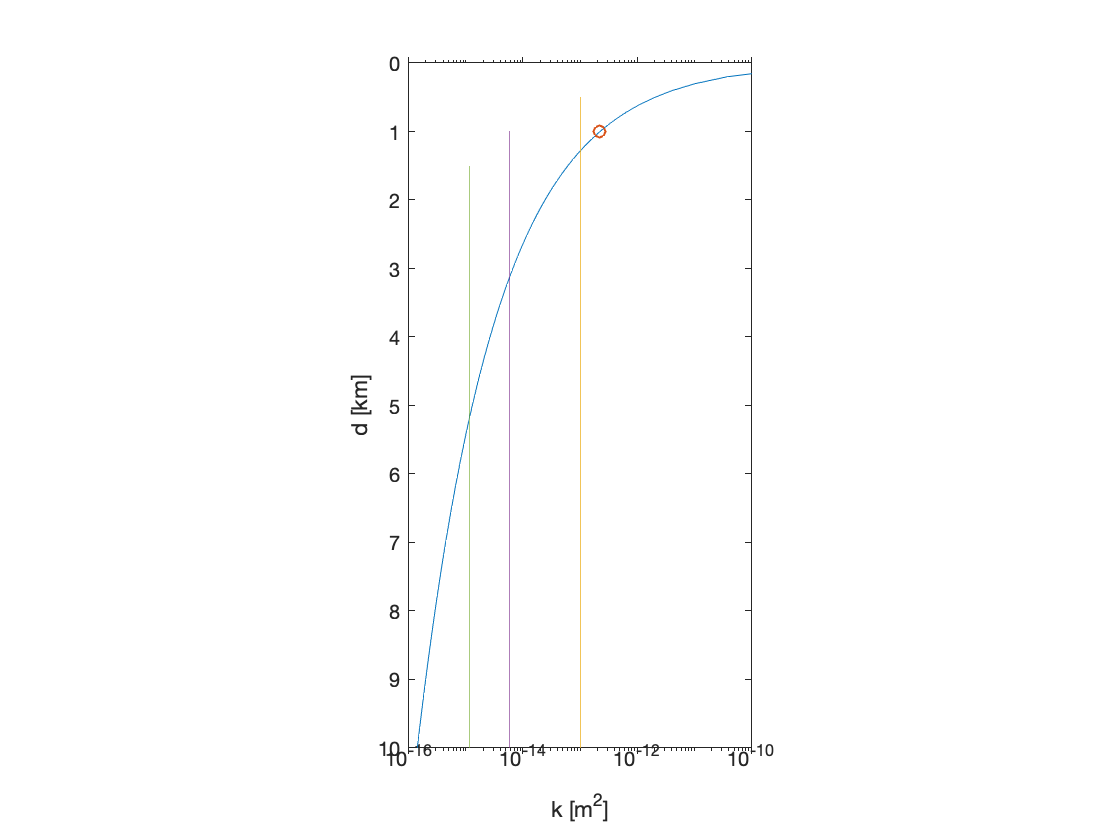


figure
semilogx(k(d),d), hold on
semilogx(k0,1,'o')
semilogx(kmean(.5,10)*[1 1],[.5 10],'-')
semilogx(kmean(1,10)*[1 1],[1 10],'-')
semilogx(kmean(1.5,10)*[1 1],[1.5 10],'-')
set(gca,'ydir','reverse')
xlabel 'k [m^2]', xlim([1e-16 1e-10]), ylabel 'd [km]'
pbaspect([1 2 1])

## Crustal aquifer with variable cross-section

## References

- [Clifford and Parker (2001) The Evolution of the Martian Hydrosphere: Implications for the Fate of a Primordial Ocean and the Current State of the Northern Plains, Icarus, 154(1), 40-79](https://doi.org/10.1006/icar.2001.6671)

- [Binder and Lange (1980) On the thermal history, thermal state, and related tectonism of a moon of fission origin, J. Geophys. Res., 85(B6), ﻿3194-3208](http:// https://doi-org.ezproxy.lib.utexas.edu/10.1029/JB085iB06p03194)

- [Han et al. (2014) Global characteristics of porosity and density stratification within the lunar crust from GRAIL gravity and Lunar Orbiter Laser Altimeter topography data, Geophys. Res. Lett. 41(6), ﻿1882-1889](http:// https://doi.org/10.1002/2014GL059378)

- [Manning and Ingebritsen (1999) Permeability of the continental crust: Implications of geothermal data and metamorphic systems, Rev. of Geophys., ﻿37(1), ﻿127-150](https://doi-org.ezproxy.lib.utexas.edu/10.1029/1998RG900002)